  $y_c$     :    Vertical displacement of car body Center of Mass (BOUNCE)

-   $\psi$      :   Rolling angular diplacement of the car body (ROLL)

- $y_{\textrm{bR}}$    :   Vertical displacement of the **back** RIGHT wheel+suspension assembly

- $y_{\textrm{bL}}$    :    Vertical displacement of the **back** LEFT wheel+suspension assembly

We'll use symbolic variable that match the diagram above: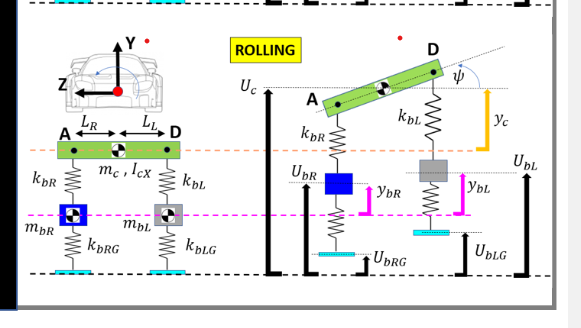

syms   L_R   L_L
syms  m_c    I_cX
syms  m_bR  m_bL
syms  k_bR  k_bL
syms  c_bR   c_bL  
syms  k_bRG  k_bLG
syms  c_bRG  c_bLG 

syms  y_c y_dot_c y_ddot_c
syms  y_dot_bR   y_dot_bL
syms  y_ddot_bR  y_ddot_bL
syms  y_bR   y_bL 

syms theta  theta_dot  theta_ddot
syms   psi    psi_dot    psi_ddot  


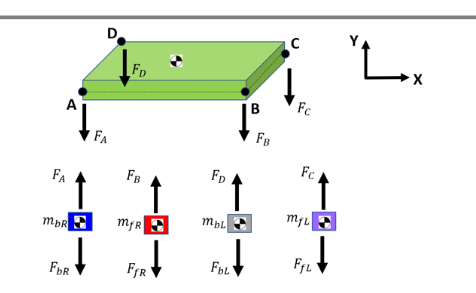

We'll define the forces shown in the above free body diagram 

F_A =   k_bR*(y_c - y_bR - L_R*psi)   +   c_bR*(y_dot_c - y_dot_bR - L_R*psi_dot);
F_D =   k_bL*(y_c - y_bL + L_L*psi)   +   c_bL*(y_dot_c - y_dot_bL + L_L*psi_dot);


Also define the TYRE spring forces $\left(F_{\textrm{bR}} \;\;\;,\;F_{\textrm{fR}} \;\;\;,\;F_{\textrm{bL}} \;\;\;,\;F_{\textrm{fL}} \right)$ acting on each Wheel/suspension assembly:

F_BLUE_bR   = k_bRG*(y_bR) + c_bRG*(y_dot_bR);
F_GREY_bL   = k_bLG*(y_bL) + c_bLG*(y_dot_bL);

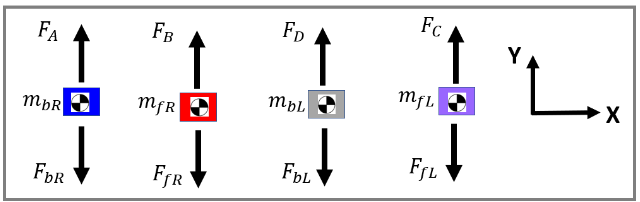

EQ_BLUE_mbR   = m_bR * y_ddot_bR ==  -1*F_BLUE_bR   + F_A;
EQ_GREY_mbL   = m_bL * y_ddot_bL ==  -1*F_GREY_bL   + F_D;

Consider the **FORCE** equation for the **GREEN Car Body**:

EQ_GREEN_mc   = m_c  * y_ddot_c  == -1*( F_A  + F_D );

EQ_GREEN_IcX  = I_cX * psi_ddot   == (F_A)*L_R  - (F_D)*L_L;


the 7 equations of motion look like this (small angle assumption) ... $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$ 

my_sys_EQ = [ EQ_GREEN_mc   ;
              EQ_GREEN_IcX  ;     
              EQ_BLUE_mbR   ;
              EQ_GREY_mbL   ;  ]

$$my\_sys\_EQ = \begin{array}{l} \left(\begin{array}{c} m_{c}\,{\ddot{y}}_{c}=\sigma_{1}-\sigma_{2}-\sigma_{4}+\sigma_{3}\\ I_{\mathrm{cX}}\,\ddot{\psi }=-L_{L}\,\left(\sigma_{2}+\sigma_{4}\right)-L_{R}\,\left(\sigma_{1}+\sigma_{3}\right)\\ m_{\mathrm{bR}}\,{\ddot{y}}_{\mathrm{bR}}=-c_{\mathrm{bRG}}\,{\dot{y}}_{\mathrm{bR}}-k_{\mathrm{bRG}}\,y_{\mathrm{bR}}-\sigma_{1}-\sigma_{3}\\ m_{\mathrm{bL}}\,{\ddot{y}}_{\mathrm{bL}}=\sigma_{2}-k_{\mathrm{bLG}}\,y_{\mathrm{bL}}-c_{\mathrm{bLG}}\,{\dot{y}}_{\mathrm{bL}}+\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{\mathrm{bR}}\,\left({\dot{y}}_{\mathrm{bR}}-{\dot{y}}_{c}+L_{R}\,\dot{\psi }\right)\\ \sigma_{2}=c_{\mathrm{bL}}\,\left({\dot{y}}_{c}-{\dot{y}}_{\mathrm{bL}}+L_{L}\,\dot{\psi }\right)\\ \sigma_{3}=k_{\mathrm{bR}}\,\left(y_{\mathrm{bR}}-y_{c}+L_{R}\,\psi \right)\\ \sigma_{4}=k_{\mathrm{bL}}\,\left(y_{c}-y_{\mathrm{bL}}+L_{L}\,\psi \right) \end{array}$$


my_4dof_sym_list = [y_c,  psi,    y_bR,  y_bL]

$$my\_4dof\_sym\_list = \left(\begin{array}{cccc} y_{c} & \psi & y_{\mathrm{bR}} & y_{\mathrm{bL}} \end{array}\right)$$


my_4dof_str_list = string(my_4dof_sym_list);


The [`equationsToMatrix()`](matlab:  web(fullfile(docroot, 'symbolic/sym.equationstomatrix.html'))) function will rearrange our 7 equations of motion into this $A\;\ldotp Z=b$  form:

my_Z_vars = [ y_ddot_c, psi_ddot,  y_ddot_bR,  y_ddot_bL, ...
               y_dot_c, psi_dot,    y_dot_bR,   y_dot_bL, ...
                   y_c,     psi,        y_bR,      y_bL   ];   
    
[A, b]    = equationsToMatrix(my_sys_EQ, my_Z_vars)    

$$A = \begin{array}{l} \left(\begin{array}{cccccccccccc} m_{c} & 0 & 0 & 0 & c_{\mathrm{bL}}+c_{\mathrm{bR}} & \sigma_{2} & -c_{\mathrm{bR}} & -c_{\mathrm{bL}} & k_{\mathrm{bL}}+k_{\mathrm{bR}} & \sigma_{1} & -k_{\mathrm{bR}} & -k_{\mathrm{bL}}\\ 0 & I_{\mathrm{cX}} & 0 & 0 & \sigma_{2} & c_{\mathrm{bL}}\,{L_{L}}^{2}+c_{\mathrm{bR}}\,{L_{R}}^{2} & L_{R}\,c_{\mathrm{bR}} & -L_{L}\,c_{\mathrm{bL}} & \sigma_{1} & k_{\mathrm{bL}}\,{L_{L}}^{2}+k_{\mathrm{bR}}\,{L_{R}}^{2} & L_{R}\,k_{\mathrm{bR}} & -L_{L}\,k_{\mathrm{bL}}\\ 0 & 0 & m_{\mathrm{bR}} & 0 & -c_{\mathrm{bR}} & L_{R}\,c_{\mathrm{bR}} & c_{\mathrm{bR}}+c_{\mathrm{bRG}} & 0 & -k_{\mathrm{bR}} & L_{R}\,k_{\mathrm{bR}} & k_{\mathrm{bR}}+k_{\mathrm{bRG}} & 0\\ 0 & 0 & 0 & m_{\mathrm{bL}} & -c_{\mathrm{bL}} & -L_{L}\,c_{\mathrm{bL}} & 0 & c_{\mathrm{bL}}+c_{\mathrm{bLG}} & -k_{\mathrm{bL}} & -L_{L}\,k_{\mathrm{bL}} & 0 & k_{\mathrm{bL}}+k_{\mathrm{bLG}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{L}\,k_{\mathrm{bL}}-L_{R}\,k_{\mathrm{bR}}\\ \sigma_{2}=L_{L}\,c_{\mathrm{bL}}-L_{R}\,c_{\mathrm{bR}} \end{array}$$

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

Great, so now we can finally "extract" our classic $M,C,K,F$ matrices:

M_mat = A(:,  1:4)

$$M\_mat = \left(\begin{array}{cccc} m_{c} & 0 & 0 & 0\\ 0 & I_{\mathrm{cX}} & 0 & 0\\ 0 & 0 & m_{\mathrm{bR}} & 0\\ 0 & 0 & 0 & m_{\mathrm{bL}} \end{array}\right)$$

C_mat = A(:,  5:8)

$$C\_mat = \left(\begin{array}{cccc} c_{\mathrm{bL}}+c_{\mathrm{bR}} & L_{L}\,c_{\mathrm{bL}}-L_{R}\,c_{\mathrm{bR}} & -c_{\mathrm{bR}} & -c_{\mathrm{bL}}\\ L_{L}\,c_{\mathrm{bL}}-L_{R}\,c_{\mathrm{bR}} & c_{\mathrm{bL}}\,{L_{L}}^{2}+c_{\mathrm{bR}}\,{L_{R}}^{2} & L_{R}\,c_{\mathrm{bR}} & -L_{L}\,c_{\mathrm{bL}}\\ -c_{\mathrm{bR}} & L_{R}\,c_{\mathrm{bR}} & c_{\mathrm{bR}}+c_{\mathrm{bRG}} & 0\\ -c_{\mathrm{bL}} & -L_{L}\,c_{\mathrm{bL}} & 0 & c_{\mathrm{bL}}+c_{\mathrm{bLG}} \end{array}\right)$$

K_mat = A(:, 9:12)

$$K\_mat = \left(\begin{array}{cccc} k_{\mathrm{bL}}+k_{\mathrm{bR}} & L_{L}\,k_{\mathrm{bL}}-L_{R}\,k_{\mathrm{bR}} & -k_{\mathrm{bR}} & -k_{\mathrm{bL}}\\ L_{L}\,k_{\mathrm{bL}}-L_{R}\,k_{\mathrm{bR}} & k_{\mathrm{bL}}\,{L_{L}}^{2}+k_{\mathrm{bR}}\,{L_{R}}^{2} & L_{R}\,k_{\mathrm{bR}} & -L_{L}\,k_{\mathrm{bL}}\\ -k_{\mathrm{bR}} & L_{R}\,k_{\mathrm{bR}} & k_{\mathrm{bR}}+k_{\mathrm{bRG}} & 0\\ -k_{\mathrm{bL}} & -L_{L}\,k_{\mathrm{bL}} & 0 & k_{\mathrm{bL}}+k_{\mathrm{bLG}} \end{array}\right)$$

F_col = b

$$F\_col = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0 \end{array}\right)$$

## Convert to Simulink blocks

$M,C,K,F$ matrices into Simulink blocks.

tf_i_should_create_SL_blocks = false;

if(tf_i_should_create_SL_blocks)
    MODEL_NAME = 'bh_tmp_model_WILL_BE_DELETED';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    purple_str = '[0.6, 0.6, 1]';
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_M_mat'], M_mat);
    matlabFunctionBlock( [MODEL_NAME,'/my_C_mat'], C_mat);    
    matlabFunctionBlock( [MODEL_NAME,'/my_K_mat'], K_mat);   
    matlabFunctionBlock( [MODEL_NAME,'/my_F_col'], F_col);
    
    % make the blocks a YELLOW color
    set_param([MODEL_NAME,'/my_M_mat'],'BackgroundColor',purple_str,'Position', [-325   262  -190   478]);
    set_param([MODEL_NAME,'/my_C_mat'],'BackgroundColor',purple_str,'Position', [45   -46   180   271]);    
    set_param([MODEL_NAME,'/my_K_mat'],'BackgroundColor',purple_str,'Position', [45   308   180   617]);
    set_param([MODEL_NAME,'/my_F_col'],'BackgroundColor',purple_str,'Position', [610     2   735   563]);    
end       

## Modal Analysis

Before we simulate(aka solve) our derived equations of motion, let's do a MODAL analysis of the system.  Consider the **UNdamped** homogeneous system:

- $M\ldotp \ddot{X} \;+\;K\ldotp X\;=0$  where $X\;\in R^{\;N\times 1}$

And let's look for a harmonic solution of the form:

- 
$$X\left(t\right)=v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$\dot{X} \left(t\right)=\;\;\;\;\;\;\;\;\;\;i\ldotp \omega \;\ldotp X\left(t\right)$$


- 
$$\ddot{X} \left(t\right)=\;\;\;-1\ldotp \omega^2 \ldotp X\left(t\right)\;$$


Then our ODE becomes:

- 
$$\left\lbrack -M\ldotp \omega^2 \;\;+\;\;K\right\rbrack \ldotp X\left(t\right)\;=\;0$$


- 
$$K\ldotp X\left(t\right)=M\ldotp X\left(t\right)\ldotp \omega^2$$


- 
$$M^{-1} \ldotp K\ldotp X\left(t\right)=\omega^2 \ldotp X\left(t\right)$$


- 
$$M^{-1} \ldotp K\ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t} =\omega^2 \ldotp v\ldotp e^{\;i\ldotp \omega \;\ldotp t}$$


- 
$$M^{-1} \ldotp K\ldotp v=\omega^2 \ldotp v$$


- $A\ldotp v=\lambda \;\ldotp v$       where  $\lambda =\omega^2$  and $A=M^{-1} \ldotp K$

The last equation is the **classic Eigenvalue problem**.  So let's solve this in MATLAB using the [`eig()`](matlab: doc eig) function:

First we need some NUMERIC values for our car's parameters(ie: mass, damping, stiffness).

- These numeric parameters are in an EXCEL file [`bh_7dof_car_database.xlsx`](matlab:  winopen( "bh_7dof_car_database.xlsx"))

OBJ_car_params =  bh_7dof_car_database_CLS("bh_7dof_car_database.xlsx","PARAMS_SET_A", "IC_SET_A");
OBJ_car_params.car_tab

ans = 29×4 table
              Name        Value       Units                     Description                
             _______    _________    ________    __________________________________________

    m_c      "m_c"            433    "kg"        "Mass of car body"                        
    I_cZ     "I_cZ"             0    "kg.m^2"    "Inertia (Z-axis) of car body"            
    I_cX     "I_cX"          82.7    "kg.m^2"    "Inertia (X-axis) of car body"            
    m_bR     "m_bR"          56.1    "kg"        "Mass of back RIGHT wheel and suspension" 
    m_fR     "m_fR"             0    "kg"        "Mass of front RIGHT wheel and suspension"
    m_bL     "m_bL"          56.1    "kg"        "Mass of back LEFT wheel and suspension"  
    

Let's now populate our system $M,C,K$matrices

- This is done in a subfunction `LOC_get_MCK` at the bottom of this script 

[M_num, C_num, K_num ] = LOC_get_MCK(M_mat, C_mat, K_mat, OBJ_car_params);

$$M = \left(\begin{array}{cccc} 433 & 0 & 0 & 0\\ 0 & \frac{827}{10} & 0 & 0\\ 0 & 0 & \frac{561}{10} & 0\\ 0 & 0 & 0 & \frac{561}{10} \end{array}\right)$$

$$C = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$K = \left(\begin{array}{cccc} 41000 & 0 & -20500 & -20500\\ 0 & \frac{46125}{2} & 15375 & -15375\\ -20500 & 15375 & 167700 & 0\\ -20500 & -15375 & 0 & 167700 \end{array}\right)$$


whos  M_num  C_num  K_num

  Name       Size            Bytes  Class     Attributes

  C_num      4x4               128  double              
  K_num      4x4               128  double              
  M_num      4x4               128  double              



 Now solve the classic Eigenvalue problem using MATLAB's [`eig()`](matlab: doc eig) function:

A            = inv(M_num) * K_num;
[eVec, eVal] = eig(A)

eVec =    -0.9846    0.0230    0.0000   -0.0000
         0         0    0.9902    0.0953
   -0.1238   -0.7069   -0.0988    0.7039
   -0.1238   -0.7069    0.0988   -0.7039


eVal = 1.0e+03 *

    0.0828         0         0         0
         0    3.0012         0         0
         0         0    0.2418         0
         0         0         0    3.0264



whos eVec   eVal

  Name      Size            Bytes  Class     Attributes

  eVal      4x4               128  double              
  eVec      4x4               128  double              



**Sort the eigenvector columns based on the ascending order of the eigenvalues:**

[~,ind] = sort( diag(eVal) );

eVec = eVec(:, ind);
eVal = eVal(:, ind);

Let's normalise the eigenvectors such that:  

-   
$$I\;\;={\;\;V}^T \ldotp M\ldotp V$$


- 
$$\;\Omega^{2\;} =\;\;V^T \ldotp K\ldotp V$$


tmp         = eVec.' * M_num * eVec;
tmp_row     =  diag(tmp)';
eVec_PHI    = eVec ./ sqrt( tmp_row );

Im_mat      = eVec_PHI.' * M_num * eVec_PHI

Im_mat =     1.0000   -0.0000   -0.0000         0
   -0.0000    1.0000         0   -0.0000
   -0.0000         0    1.0000   -0.0000
   -0.0000   -0.0000   -0.0000    1.0000


w2_mat      = eVec_PHI.' * K_num * eVec_PHI

w2_mat = 1.0e+03 *

    0.0828   -0.0000    0.0000   -0.0000
   -0.0000    0.2418         0    0.0000
    0.0000         0    3.0012   -0.0000
    0.0000    0.0000   -0.0000    3.0264


#### Great, so let's summarise what we have. 

Our UNdamped frequencies of vibration are:   $\omega \;\;\;\left\lbrack \frac{\textrm{rad}}{\sec }\right\rbrack$:

w_list = sqrt( diag(w2_mat) );
w_table = array2table( [w_list, w_list/(2*pi)], "VariableNames", {'w_radpersec', 'f_Hz'}  )

w_table = 4×2 table
    w_radpersec     f_Hz 
    ___________    ______

      9.0986       1.4481
      15.549       2.4747
      54.783        8.719
      55.013       8.7555


Our MODE shapes are the columns of the matrix:

eVec_PHI

eVec_PHI =    -0.0480    0.0000    0.0031   -0.0000
         0    0.1092         0    0.0127
   -0.0060   -0.0109   -0.0942    0.0938
   -0.0060    0.0109   -0.0942   -0.0938


We can visualize the mode shapes.  

- For visualiztion, let's normalise each mode shape column by it's largest absolute value ... so that we can see which DOF makes the dominant contribution in each mode 

NUM_DOF             =   size(eVec_PHI,1);
MAX_NORM_eVec_PHI   = eVec_PHI ./ repmat(max(abs(eVec_PHI)), NUM_DOF, 1);

Create a table of our MAX normalised Mode shapes:

mode_table = array2table( MAX_NORM_eVec_PHI, ...
                          "VariableNames",  "MODE_"+[1:4], ...
                          "RowNames"     ,  my_4dof_str_list ) 

mode_table = 4×4 table
             MODE_1       MODE_2       MODE_3       MODE_4   
            ________    __________    ________    ___________

    y_c           -1    1.9372e-17    0.032578    -9.5388e-17
    psi            0             1           0        0.13533
    y_bR    -0.12572     -0.099749          -1              1
    y_bL    -0.12572      0.099749          -1             -1


And visualize the MAX normalised Mode shapes in a HEATMAP

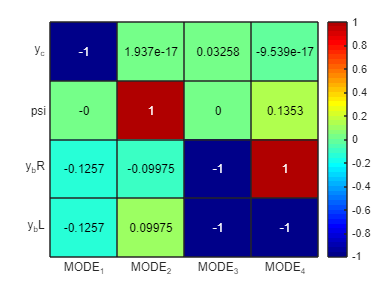

figure;
    heatmap( ("MODE_"+[1:4]), my_4dof_str_list, MAX_NORM_eVec_PHI, "Colormap", jet(50)  );

# **Next steps:**

In the previous sections we derived the equations of motion for the 7-dof car model  These ODEs had the familiar form:

- $M\ldotp \ddot{X} \;+\;C\ldotp \dot{X} \;+\;K\ldotp X\;=\;F$     where   $X\in R^{\;7\times 1}$     and       $X^T =\left\lbrack \begin{array}{ccccccc}
y_c  & \theta  & \psi  & y_{\textrm{bR}}  & y_{\textrm{fR}}  & y_{\textrm{bL}}  & y_{\textrm{fL}} 
\end{array}\right\rbrack$

We also converted the $M,C,K,F$ matrices into Simulink blocks.  These Simulink blocks can then be used inside a Simulink model.  We've already copied these blocks into the Simulink file [`bh_COMPONENT_model_7dof_car_HAND.slx`](matlab:  open bh_COMPONENT_model_7dof_car_HAND.slx) .  

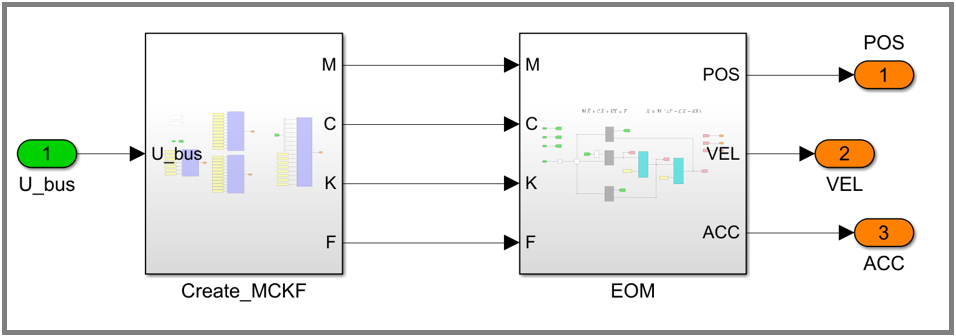

So ? - So our **next step** is to simulate these Brain derived equations of motion and explore how the dynamics of the car system respond to different types of excitation.

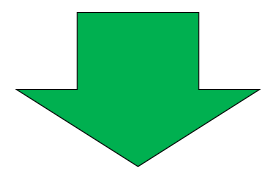

- In the file [`DEMO_02_bh_7dof_launch_sim_modal.mlx`](matlab:  edit DEMO_02_bh_7dof_launch_sim_modal.mlx) we'll explore the significance of the car's MODAL frequencies - specifically what happens when we excite the car at/near these MODAL frequencies.

- In the file [`DEMO_03_bh_7dof_launch_sim_humps.mlx`](matlab:  edit DEMO_03_bh_7dof_launch_sim_humps.mlx) we'll explore how the car dynamics respond when we excite the car using a road profile made up of a series of speed humps

# **Local Subfunctions only beyond this point**

Replace the symbolic symbols with NUMERIC values

function [M,C,K] = LOC_get_MCK(M_sym, C_sym, K_sym, OBJ_car_params)

    syms L_b  L_f    L_R   L_L
    syms  m_c    I_cZ    I_cX
    syms  m_bR   m_fR    m_bL    m_fL
    syms  k_bR   k_fR    k_bL    k_fL
    syms  c_bR   c_fR    c_bL    c_fL
    syms  k_bRG  k_fRG   k_bLG   k_fLG
    syms  c_bRG  c_fRG   c_bLG   c_fLG
    
    the_sym_list = [ L_b,    L_f,     L_R,     L_L,   ...
                     m_c,    I_cZ,    I_cX,           ... 
                     m_bR,   m_fR,    m_bL,    m_fL,  ...
                     k_bR,   k_fR,    k_bL,    k_fL,  ...
                     c_bR,   c_fR,    c_bL,    c_fL,  ...
                     k_bRG,  k_fRG,   k_bLG,   k_fLG, ...
                     c_bRG,  c_fRG,   c_bLG,   c_fLG      ];
    
    the_value_list = zeros(size(the_sym_list));
    
    for kk=1:length(the_sym_list)
        NAME                = string(  the_sym_list(kk)  );
        the_value_list(kk)  = OBJ_car_params.car_tab{NAME, "Value"};
    end
    
    M = subs(M_sym, the_sym_list, the_value_list)
    C = subs(C_sym, the_sym_list, the_value_list)
    K = subs(K_sym, the_sym_list, the_value_list)
    
    M = double(M);
    C = double(C);
    K = double(K);

end